# MidTerm

# Name - Vinay Patil

# Net Id - vpatil3

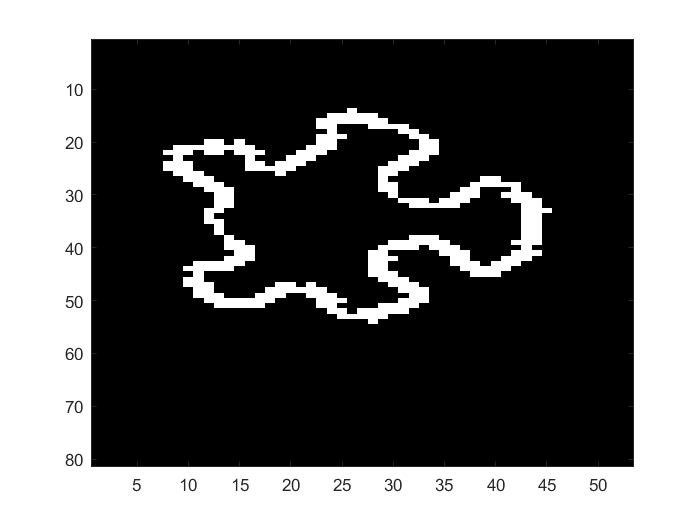

%Preprocessing steps for orange_piece.jpg
orangePiece = double(imread("orange_piece.jpg"));
%Resize orangePiece to lower the resolution by a factor of 5
newOrangePieceRows = ceil(size(orangePiece,1)/5);
newOrangePieceCols = ceil(size(orangePiece,2)/5);
orangePiece = imresize(orangePiece,[newOrangePieceRows newOrangePieceCols]);
%Changing to grayScale
orangePiece = 0.2989*orangePiece(:,:,1)+0.5870*orangePiece(:,:,2)+0.1140*orangePiece(:,:,3);
%Removing noise from the image
orangePieceGray = medfilt2(orangePiece);
%Detecting edges and binarizing
ksx = reshape([-1 -2 -1 0 0 0 1 2 1], 3, 3 );
ksy = ksx';
gx = conv2(orangePieceGray, ksx, 'same');
gy = conv2(orangePieceGray, ksy, 'same');
orangePiece = sqrt(gx.^2 + gy.^2);
orangePiece = orangePiece>330;
angle = 45;
orangePiece = rotatePiece(orangePiece,angle);
figure
imagesc(orangePiece);

%Finding x_c and y_c
[x_coord,y_coord] = find(orangePiece >0);
x_c = round(mean(x_coord));
y_c = round(mean(y_coord));

%Finding angles for orange_piece.jpg edge points
dir_grad_piece = atan2(gy,gx);
dir_grad_piece(orangePiece==0) = 0;
dir_grad_piece = round(dir_grad_piece*180/pi);

%Getting unique angles and ignoring non-edge angles i.e 0
unique_angles = unique(dir_grad_piece);
unique_angles = unique_angles(unique_angles~=0);

%Constructing R-Table
R_Table = struct;
count = 1;
for phi_degree=unique_angles'
    [x,y] = find(dir_grad_piece==phi_degree);
    x_prime = x_c - x;
    y_prime = y_c - y;
    r = sqrt(x_prime.^2 + y_prime.^2);
    alpha_rad = atan2(y_prime,x_prime);
    R_Table(count).phi = phi_degree;
    R_Table(count).alpha = round(alpha_rad*180/pi)';
    R_Table(count).length = r';
    count = count + 1;
end

struct2table(R_Table);


%Preprocessing steps for main.jpg
colormap('gray')

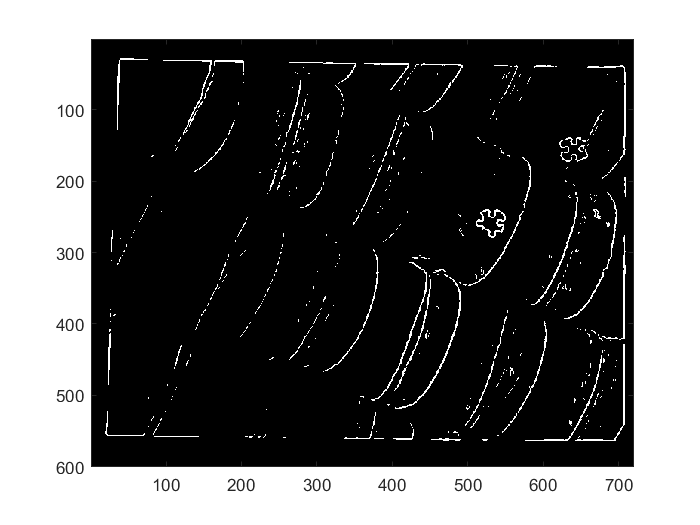

main = double(imread("main.jpg"));
%Resize main to lower the resolution by a factor of 5
newMainRows = ceil(size(main,1)/5);
newMainCols = ceil(size(main,2)/5);
main = imresize(main,[newMainRows newMainCols]);
%Changing to grayScale
main = 0.2989*main(:,:,1)+0.5870*main(:,:,2)+0.1140*main(:,:,3);
%Removing noise from the image
mainGray = medfilt2(main);
%Detecting edges and binarizing
ksx = reshape([-1 -2 -1 0 0 0 1 2 1], 3, 3 );
ksy = ksx';
gx = conv2(mainGray, ksx, 'same');
gy = conv2(mainGray, ksy, 'same');
main = sqrt(gx.^2 + gy.^2);
main = main>250;
imagesc(main);

## 1) Generalized Hough Transform

%Finding angles for main.jpg edge points
dir_grad_main = atan2(gy,gx);
dir_grad_main(main==0) = 0;
dir_grad_main = round(dir_grad_main*180/pi);

%Getting unique angles and ignoring non-edge angles i.e 0
unique_angles = unique(dir_grad_main);
unique_angles = unique_angles(unique_angles~=0);

%Building accumulation matrix
rows = size(main,1);
cols = size(main,2);
no_of_rotations = 360/45;
acc_matrix = zeros(rows,cols,no_of_rotations);
R_Table_New = R_Table;

for rot=0:no_of_rotations-1
    if(rot>0)
        R_Table_New = rotatePhi(R_Table,rot);
    end
    
    for phi_degree=unique_angles'
        [x,y] = find(dir_grad_main==phi_degree);
        matchedLogical = [R_Table_New.phi]==phi_degree;
        
        if sum(matchedLogical)==1
            match = R_Table_New(matchedLogical);
            nums = length(match.alpha); % The length vector will also be of same size, can consider either here
            for i=1:nums
                x_candidate = round(x + match.length(i)*cos(match.alpha(i)*pi/180));
                y_candidate = round(y + match.length(i)*sin(match.alpha(i)*pi/180));
                
                %Getting valid coordintes for accumulator matrix
                coord_x = x_candidate<=rows & x_candidate>0;
                coord_y = y_candidate<=cols & y_candidate>0;
                valids = coord_x & coord_y;
                x_candidate = x_candidate(valids);
                y_candidate = y_candidate(valids);
                
                count = sum(valids);
                for j=1:count
                    acc_matrix(x_candidate(j),y_candidate(j),rot+1) = acc_matrix(x_candidate(j),y_candidate(j),rot+1) + 1;
                end
            end
        end
    end
end

%Finding optimal accumulation matrix
max_val = 0;
x_cen = 200;
y_cen = 200;
struct2table(R_Table)

ans = 199×3 table
    phi        alpha           length   
    ____    ____________    ____________

    -179    [1×2 double]    [1×2 double]
    -178    [        11]    [   16.2788]
    -177    [         7]    [   16.1245]
    -176    [1×3 double]    [1×3 double]
    -173    [      -153]    [   13.4164]
    -171    [       -67]    [    7.6158]
    -167    [         7]    [   17.1172]
    -166    [      -117]    [   17.8885]
    -165    [1×2 double]    [1×2 double]
    -164    [      -152]    [   14.7648]
    -163    [1×2 double]    [1×2 double]
    -161    [      -155]    [   14.3178]
    -160    [1×2 double]    [1×2 double]
    -159    [         9]    [   19.2354]
    -157    [         9]    [   18.2483]
    -154    [1×2 double]    [1×2 double]


ans = 199×3 table
    phi        alpha           length   
    ____    ____________    ____________

    -179    [1×2 double]    [1×2 double]
    -178    [        11]    [   16.2788]
    -177    [         7]    [   16.1245]
    -176    [1×3 double]    [1×3 double]
    -173    [      -153]    [   13.4164]
    -171    [       -67]    [    7.6158]
    -167    [         7]    [   17.1172]
    -166    [      -117]    [   17.8885]
    -165    [1×2 double]    [1×2 double]
    -164    [      -152]    [   14.7648]
    -163    [1×2 double]    [1×2 double]
    -161    [      -155]    [   14.3178]
    -160    [1×2 double]    [1×2 double]
    -159    [         9]    [   19.2354]
    -157    [         9]    [   18.2483]
    -154    [1×2 double]    [1×2 double]


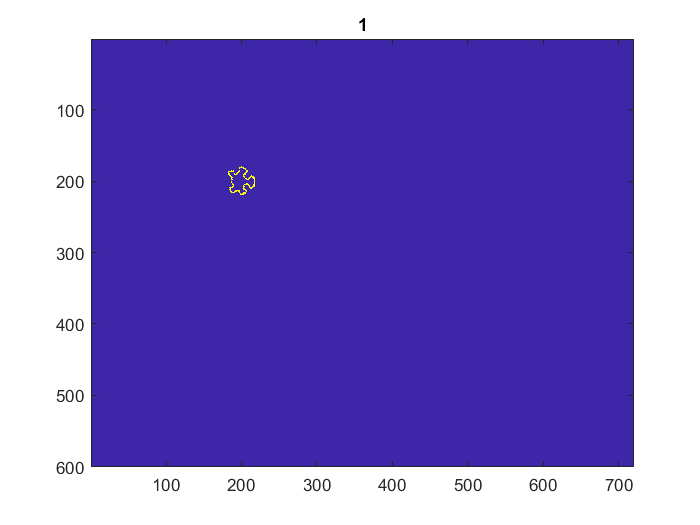

ans = 199×3 table
    phi        alpha           length   
    ____    ____________    ____________

    -134    [1×2 double]    [1×2 double]
    -133    [        56]    [   16.2788]
    -132    [        52]    [   16.1245]
    -131    [1×3 double]    [1×3 double]
    -128    [      -108]    [   13.4164]
    -126    [       -22]    [    7.6158]
    -122    [        52]    [   17.1172]
    -121    [       -72]    [   17.8885]
    -120    [1×2 double]    [1×2 double]
    -119    [      -107]    [   14.7648]
    -118    [1×2 double]    [1×2 double]
    -116    [      -110]    [   14.3178]
    -115    [1×2 double]    [1×2 double]
    -114    [        54]    [   19.2354]
    -112    [        54]    [   18.2483]
    -109    [1×2 double]    [1×2 double]


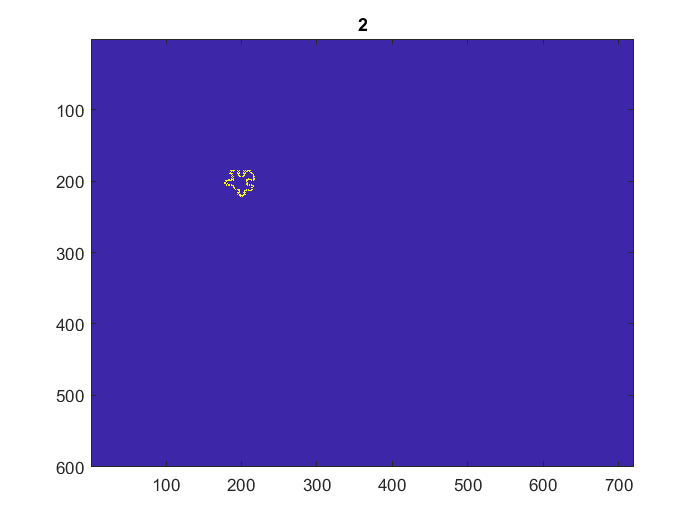

ans = 199×3 table
    phi       alpha           length   
    ___    ____________    ____________

    -89    [1×2 double]    [1×2 double]
    -88    [       101]    [   16.2788]
    -87    [        97]    [   16.1245]
    -86    [1×3 double]    [1×3 double]
    -83    [       -63]    [   13.4164]
    -81    [        23]    [    7.6158]
    -77    [        97]    [   17.1172]
    -76    [       -27]    [   17.8885]
    -75    [1×2 double]    [1×2 double]
    -74    [       -62]    [   14.7648]
    -73    [1×2 double]    [1×2 double]
    -71    [       -65]    [   14.3178]
    -70    [1×2 double]    [1×2 double]
    -69    [        99]    [   19.2354]
    -67    [        99]    [   18.2483]
    -64    [1×2 double]    [1×2 double]


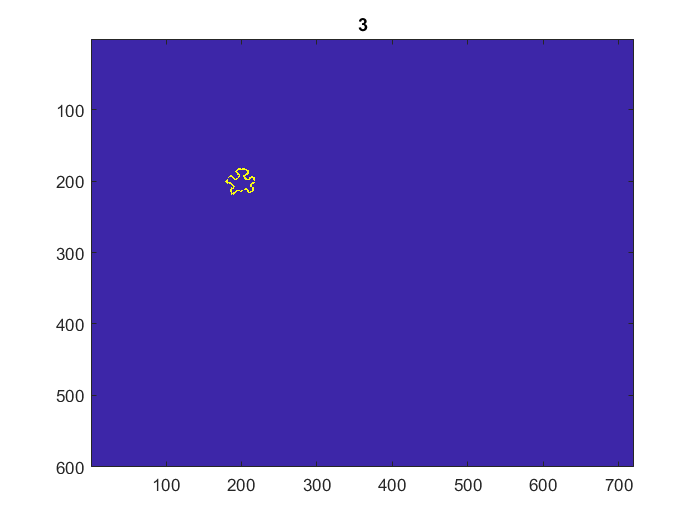

ans = 199×3 table
    phi       alpha           length   
    ___    ____________    ____________

    -44    [1×2 double]    [1×2 double]
    -43    [       146]    [   16.2788]
    -42    [       142]    [   16.1245]
    -41    [1×3 double]    [1×3 double]
    -38    [       -18]    [   13.4164]
    -36    [        68]    [    7.6158]
    -32    [       142]    [   17.1172]
    -31    [        18]    [   17.8885]
    -30    [1×2 double]    [1×2 double]
    -29    [       -17]    [   14.7648]
    -28    [1×2 double]    [1×2 double]
    -26    [       -20]    [   14.3178]
    -25    [1×2 double]    [1×2 double]
    -24    [       144]    [   19.2354]
    -22    [       144]    [   18.2483]
    -19    [1×2 double]    [1×2 double]


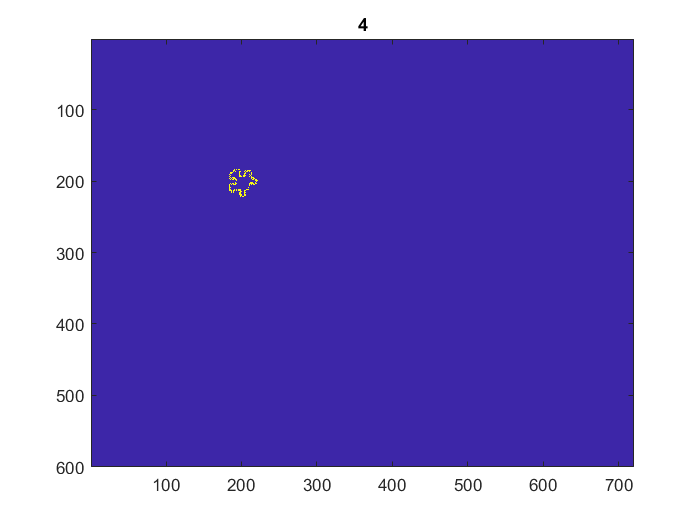

ans = 199×3 table
    phi       alpha           length   
    ___    ____________    ____________

     1     [1×2 double]    [1×2 double]
     2     [       191]    [   16.2788]
     3     [       187]    [   16.1245]
     4     [1×3 double]    [1×3 double]
     7     [        27]    [   13.4164]
     9     [       113]    [    7.6158]
    13     [       187]    [   17.1172]
    14     [        63]    [   17.8885]
    15     [1×2 double]    [1×2 double]
    16     [        28]    [   14.7648]
    17     [1×2 double]    [1×2 double]
    19     [        25]    [   14.3178]
    20     [1×2 double]    [1×2 double]
    21     [       189]    [   19.2354]
    23     [       189]    [   18.2483]
    26     [1×2 double]    [1×2 double]


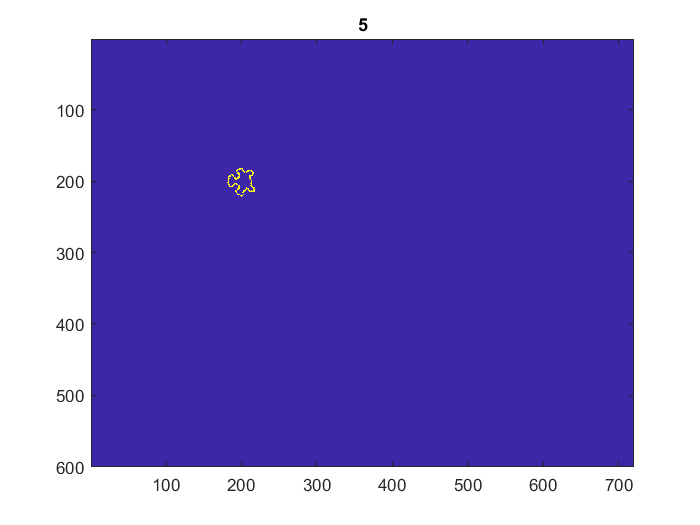

ans = 199×3 table
    phi       alpha           length   
    ___    ____________    ____________

    46     [1×2 double]    [1×2 double]
    47     [       236]    [   16.2788]
    48     [       232]    [   16.1245]
    49     [1×3 double]    [1×3 double]
    52     [        72]    [   13.4164]
    54     [       158]    [    7.6158]
    58     [       232]    [   17.1172]
    59     [       108]    [   17.8885]
    60     [1×2 double]    [1×2 double]
    61     [        73]    [   14.7648]
    62     [1×2 double]    [1×2 double]
    64     [        70]    [   14.3178]
    65     [1×2 double]    [1×2 double]
    66     [       234]    [   19.2354]
    68     [       234]    [   18.2483]
    71     [1×2 double]    [1×2 double]


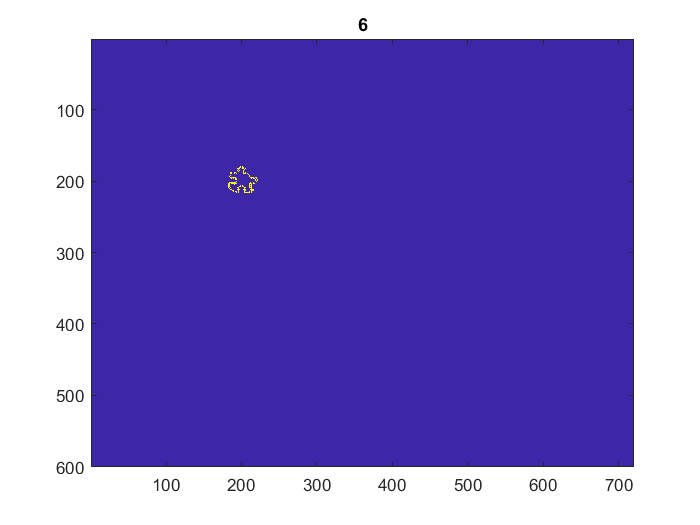

ans = 199×3 table
    phi       alpha           length   
    ___    ____________    ____________

     91    [1×2 double]    [1×2 double]
     92    [       281]    [   16.2788]
     93    [       277]    [   16.1245]
     94    [1×3 double]    [1×3 double]
     97    [       117]    [   13.4164]
     99    [       203]    [    7.6158]
    103    [       277]    [   17.1172]
    104    [       153]    [   17.8885]
    105    [1×2 double]    [1×2 double]
    106    [       118]    [   14.7648]
    107    [1×2 double]    [1×2 double]
    109    [       115]    [   14.3178]
    110    [1×2 double]    [1×2 double]
    111    [       279]    [   19.2354]
    113    [       279]    [   18.2483]
    116    [1×2 double]    [1×2 double]


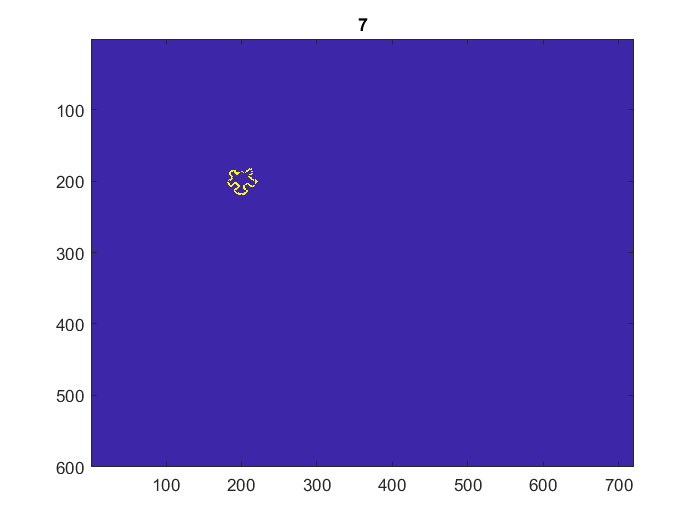

ans = 199×3 table
    phi       alpha           length   
    ___    ____________    ____________

    136    [1×2 double]    [1×2 double]
    137    [       326]    [   16.2788]
    138    [       322]    [   16.1245]
    139    [1×3 double]    [1×3 double]
    142    [       162]    [   13.4164]
    144    [       248]    [    7.6158]
    148    [       322]    [   17.1172]
    149    [       198]    [   17.8885]
    150    [1×2 double]    [1×2 double]
    151    [       163]    [   14.7648]
    152    [1×2 double]    [1×2 double]
    154    [       160]    [   14.3178]
    155    [1×2 double]    [1×2 double]
    156    [       324]    [   19.2354]
    158    [       324]    [   18.2483]
    161    [1×2 double]    [1×2 double]


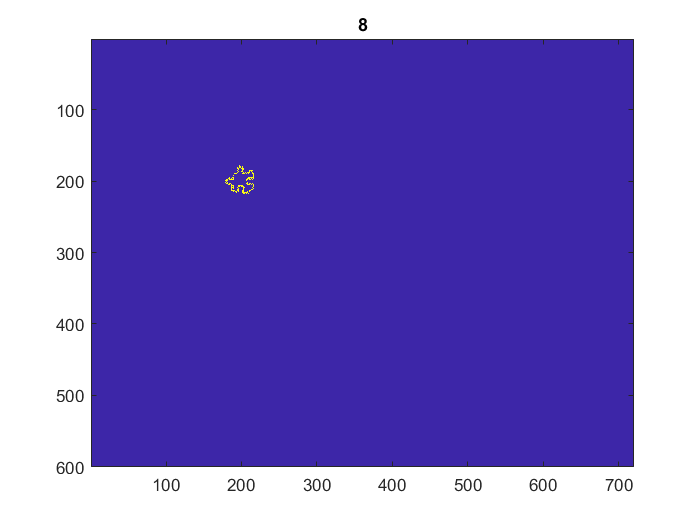

for rot_index=1:8
    
    generated_shape = zeros(rows,cols);
    table = rotatePhi(R_Table,rot_index-1);
    struct2table(table)
    
    for k=1:length(table)
        nums = length(table(k).alpha);
        for i=1:nums
            xloop = round(x_cen-(table(k).length(i)*cos(table(k).alpha(i)*pi/180)));
            yloop = round(y_cen-(table(k).length(i)*sin(table(k).alpha(i)*pi/180)));
            if xloop>0 && yloop>0 && xloop<=rows && yloop<=cols
                generated_shape(xloop,yloop) = 1;
            end
        end
    end
    
    figure
    imagesc(generated_shape);
    title(rot_index);
end

%Function to rotate the R-Table

function new_table = rotatePhi(table,rot)
for k=1:length(table)
    temp = table(k).phi + rot*45;
    
    if(temp>180)
        x = mod(temp,360);
        if(x>180)
            x = -180 + mod(x,180);
        end
        temp = x;
    end
    table(k).phi = temp;
    table(k).alpha = table(k).alpha + rot*45;
end
new_table = table;
end

%Function to rotate the puzzle piece
function rotimg = rotatePiece(piece,angle)
rotimg=zeros(size(piece));
rotmat=zeros(2,2);
rotmat(1,1)=cos(angle*pi/180);
rotmat(1,2)=-sin(angle*pi/180);
rotmat(2,1)=sin(angle*pi/180);
rotmat(2,2)=cos(angle*pi/180);
rotmat_inv=inv(rotmat);

shift=zeros(2,1);
shift(1,1)= floor(size(piece,1)/2);
shift(2,1)= floor(size(piece,2)/2);
rho=0;
for i=1:size(piece,1)
    for j=1:size(piece,2)
        newpix(1,1)=i;
        newpix(2,1)=j;
       	oldpix=round(rotmat_inv*(newpix-shift)+shift);
        if (oldpix(1,1) > 0) && (oldpix(1,1) < size(piece,1)) && (oldpix(2,1) > 0) && (oldpix(2,1) < size(piece,2))
            rho=piece(oldpix(1,1),oldpix(2,1));
        end
       	rotimg(i,j)=rho;
    end
end
end

